rrDim = tablecontent(:,"rrDim");
rrDim = table2array(rrDim)

rrDim =      3
     3
     5
     5
     5
     3
     7
     7
     3
     6


for i = 1:8
result(i) = mean(rrDim((i-1)*10+1:i*10));
end
hpc_rrdim = result(1:2:end);
pfc_rrdim = result(2:2:end);
rrDimAveraged = table([hpc_rrdim, pfc_rrdim])

rrDimAveraged = table
        Var1    
    ____________

    [1×8 double]


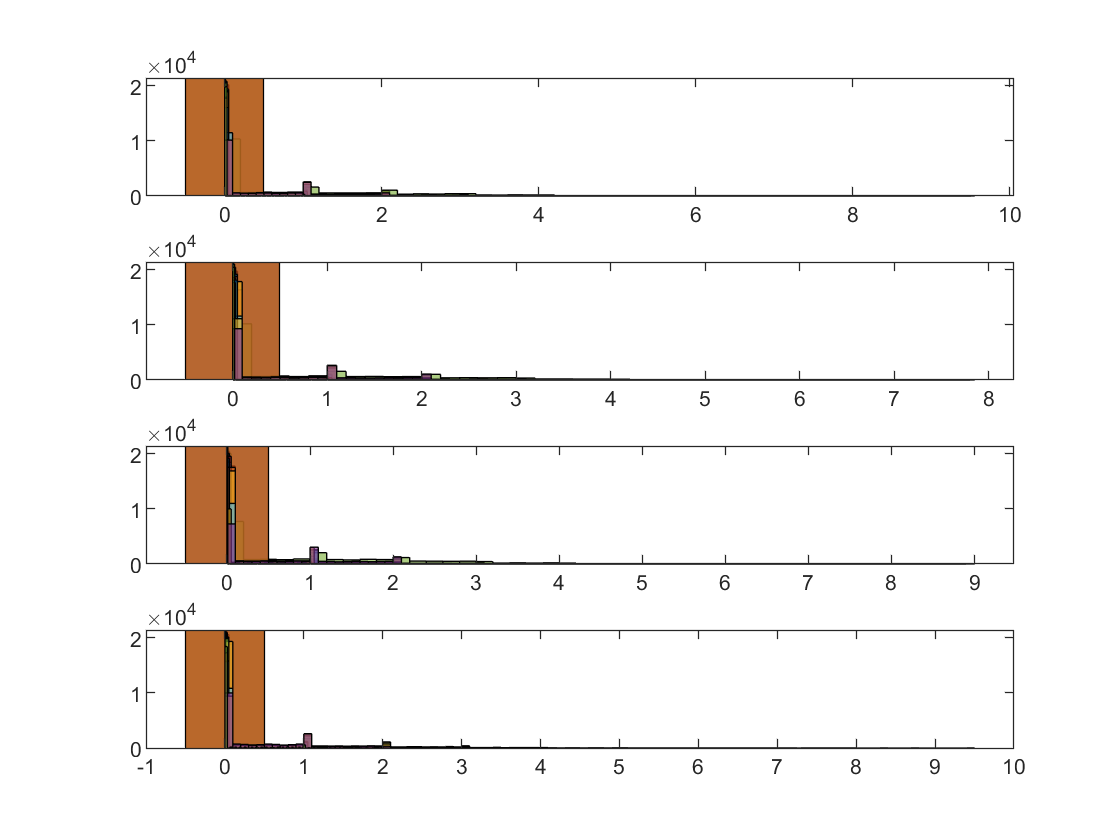














% neuron's distribution of firing rate over trials
% (spikeSampleMatrix: neuron * trials)
numNeurons = nPFCneurons+nHPCneurons;
figure(100)

fr_std = zeros(numResult, numNeurons);
for i = 1:numResult
    currSample = spikeSampleMatrix{i};
    subplot(numResult,1,i)
    for j = 1:numNeurons
        histogram(currSample(j,:))
        fr_std(i,j) = std(currSample(j,:));
        hold on
    end
end

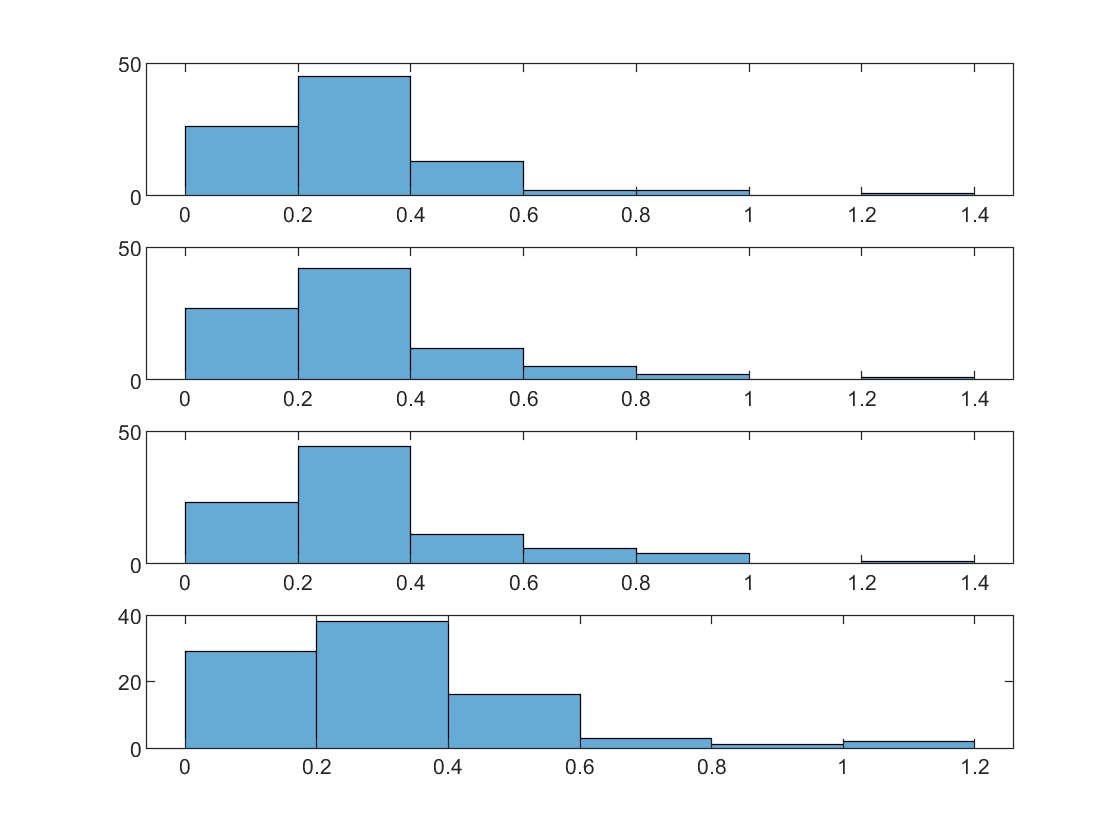

% histogram of the variability of firing rate across trial/windows
figure(101)
for i = 1:numResult
    subplot(numResult, 1, i)
    histogram(fr_std(i,:))
end

% neuron's distribution of firing rate across time bins
% consistent through the whole recording period? consistent through each
% window??

figure(102)
fr_binwise_std_session = zeros(1,numNeurons);
fr_binwise_std_trial = zeros(size(X_hpc{1},2),numNeurons);

for i = 1:numNeurons
    current = spikeRateMatrix(i,:);
    
end
